# Act Segmentacion CT-Chest

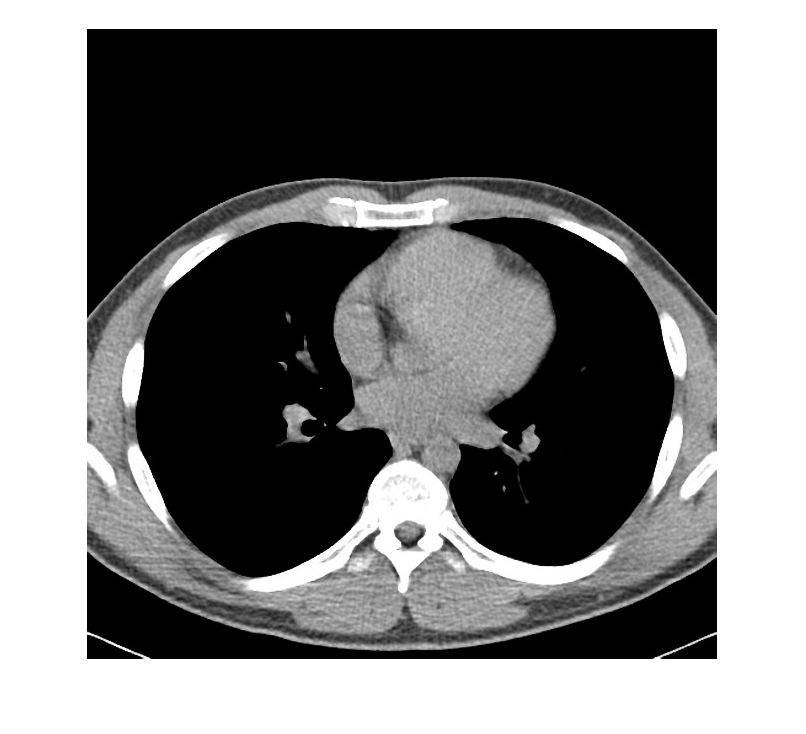


f=imread('CT_CHEST.jpeg');
f=double(f(:,:,1));
f=f/max(max(f));
figure(1)
imshow(f,[]);

## Thresholding

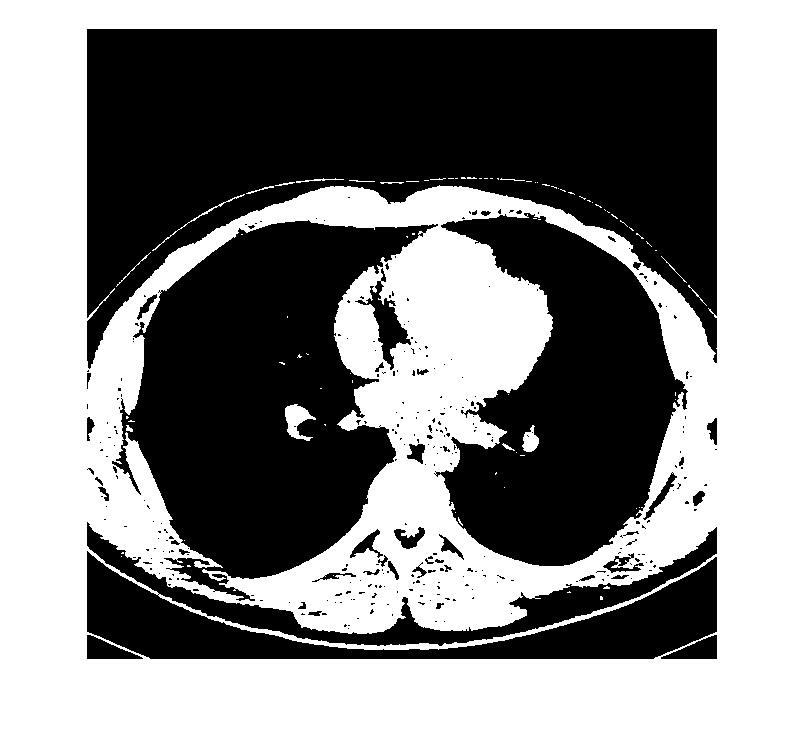

seg1 = f > 0.5;
imshow(seg1,[])

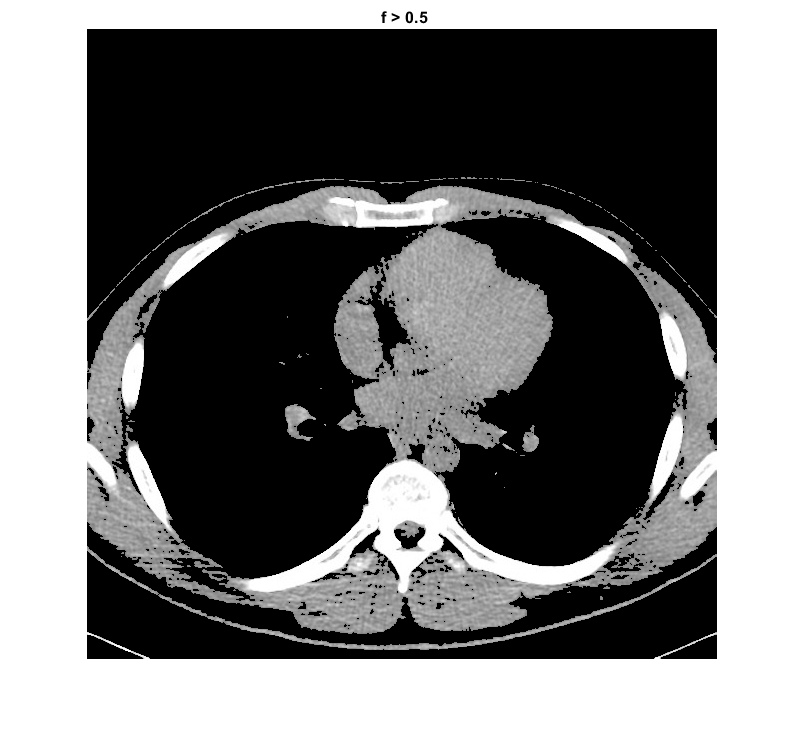

imshow(seg1.*f,[])
title(' f > 0.5')

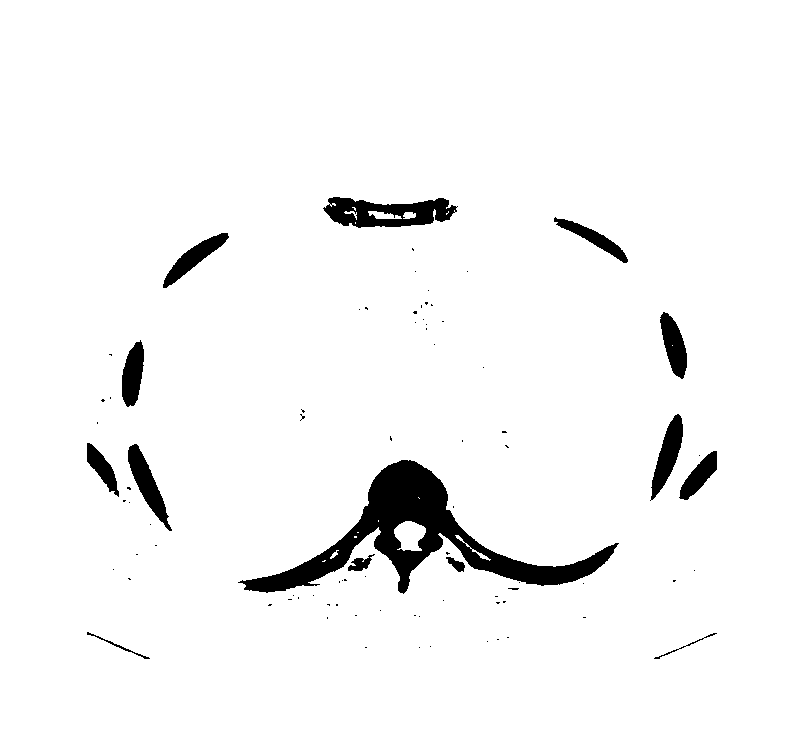

seg1 = f < 0.75;
imshow(seg1,[])

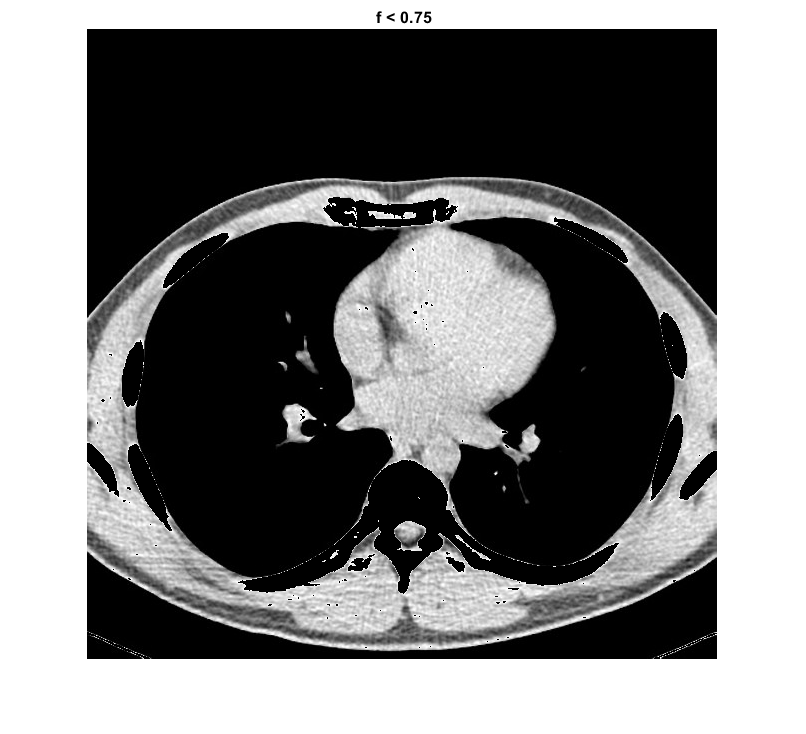

imshow(seg1.*f,[])
title(' f < 0.75')

seg = f > 0.4;
imshow(seg1, [])

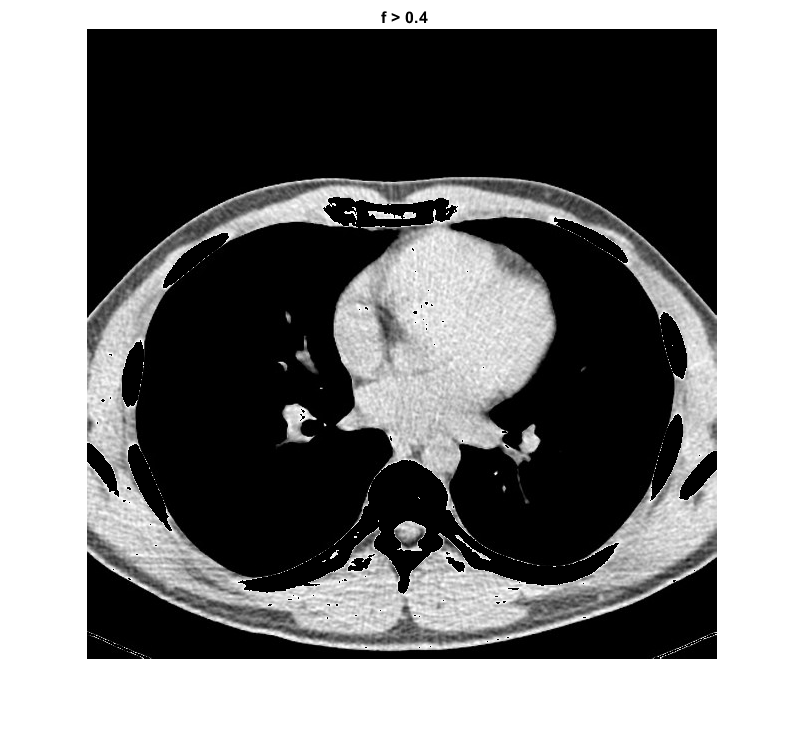

imshow(seg1.*f, [])
title(' f > 0.4')

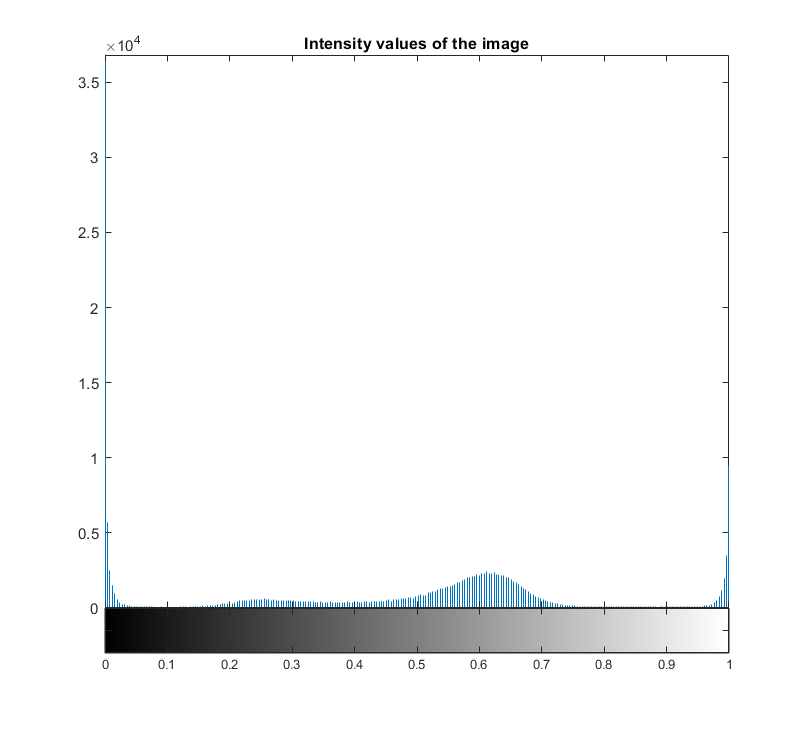

imhist(f)
title('Intensity values of the image')

% Use a third threshold based on the histogram

## Otsu method

thr = graythresh(f)

thr = 0.3294

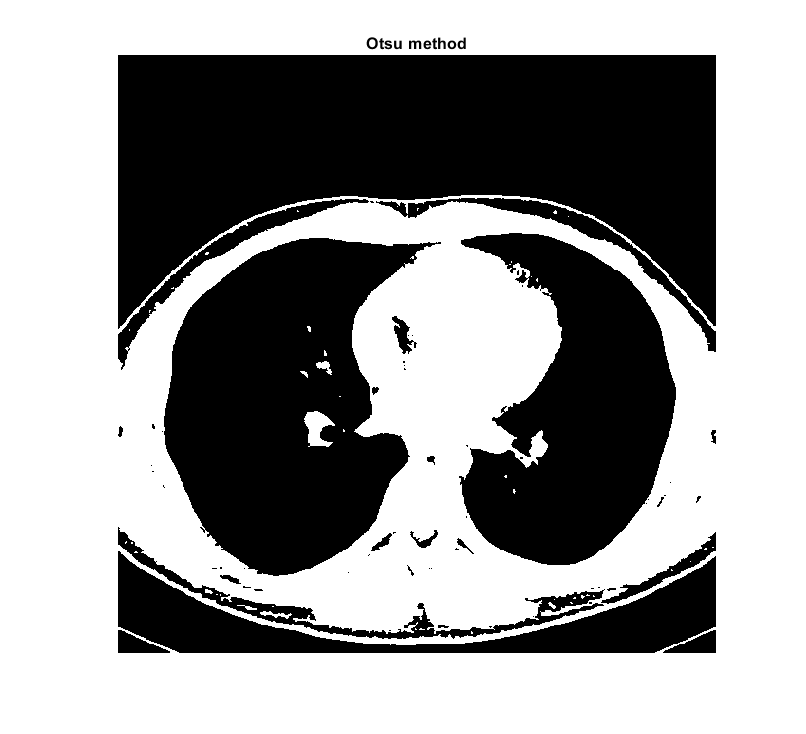

seg1 = f > thr;
imshow(seg1,[])
title('Otsu method')

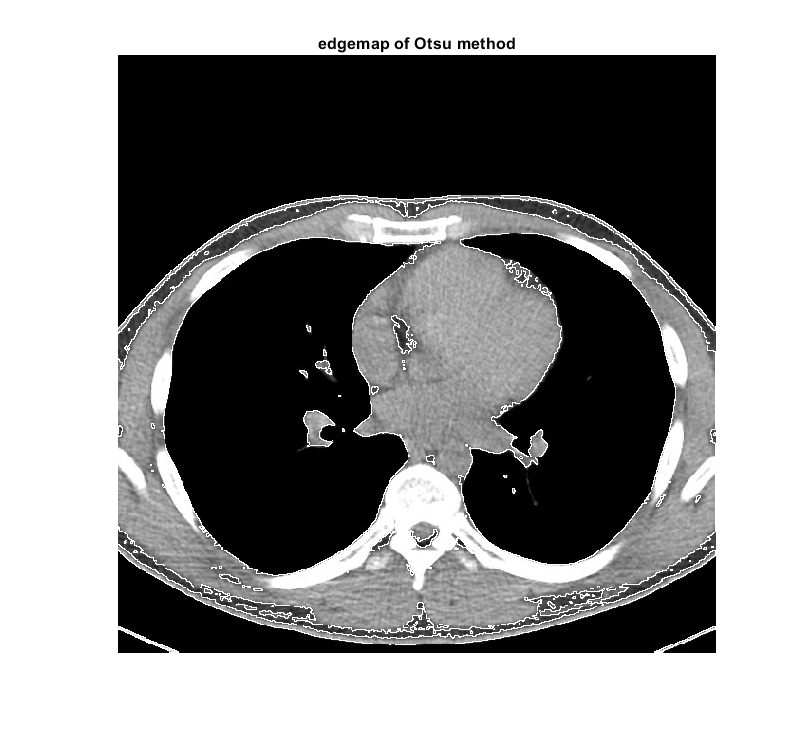

dxp=[0,1;-1,0];
dyp=[1,0;0,-1];
edgemap = abs(conv2(seg1,dxp,'same'))+abs(conv2(seg1,dyp,'same'));
imshow(f+edgemap,[0,1]);
title('edgemap of Otsu method')


% Compare the otsu provided threshold vs the one you selected in the
% preview step.
% Do you trust the Otsu treshold? 
% A = this method obtains the numerical value of the intensity scale in
% which the gray color appears. Taking that into account, we see in the
% image obtained with the Otsu method that we can appreciate most of the
% tissue appearing on the radiography.
%
% Select your own image and compute the otsu threshold

## Kmeans segmentation

%Robets Operator
dxp=[0,1;-1,0];
dyp=[1,0;0,-1];
% Disk for clossing labels
diskse= strel('disk',5);
diskse11= strel('disk',11);


%% Kmeans

% 6 class
[L,Centers] = imsegkmeans(uint8(255*f),4);
B = labeloverlay(f,L);
imshow(L,[])
colormap('hot')
title("Labeled Image")
Centers

Centers = 4×1 uint8 column vector
     1
   153
   248
    80


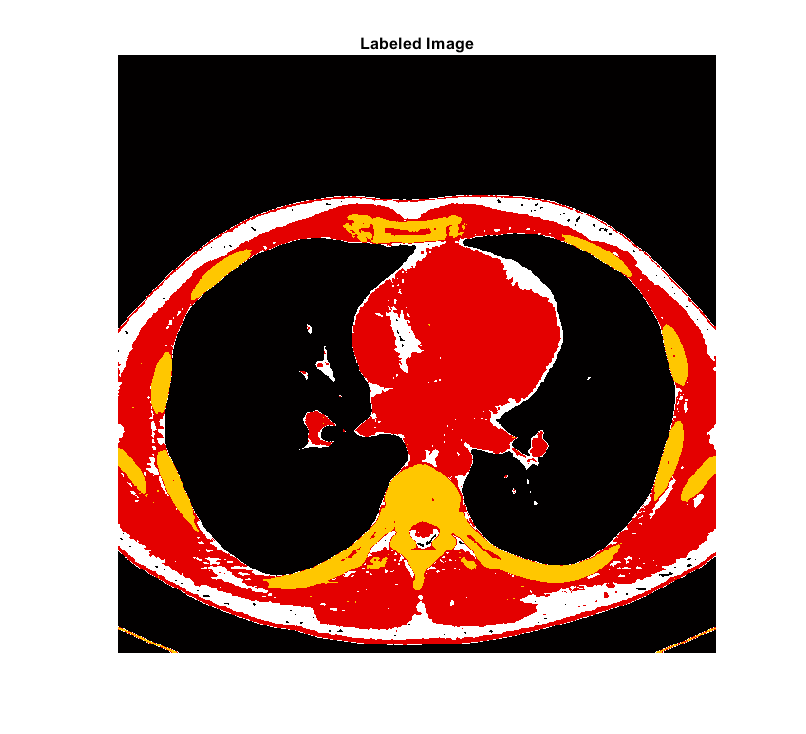

%% Clean with morphology each class

%First label
subplot(1,1,1)

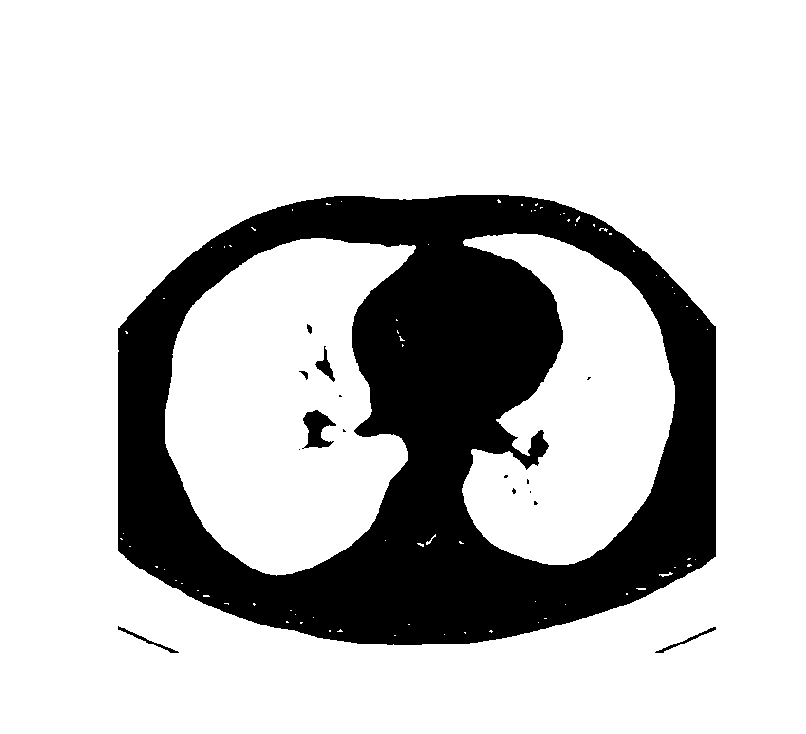

label_one = L == 1;
imshow(label_one)

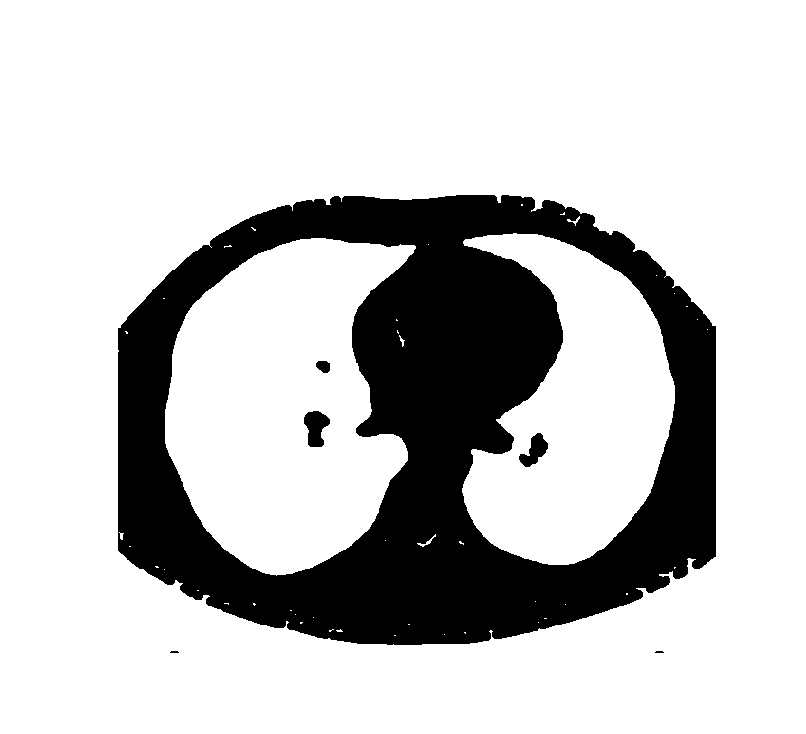

% remove false negatives wiht imclose
label_close_one = imclose(label_one,diskse);
imshow(label_close_one)

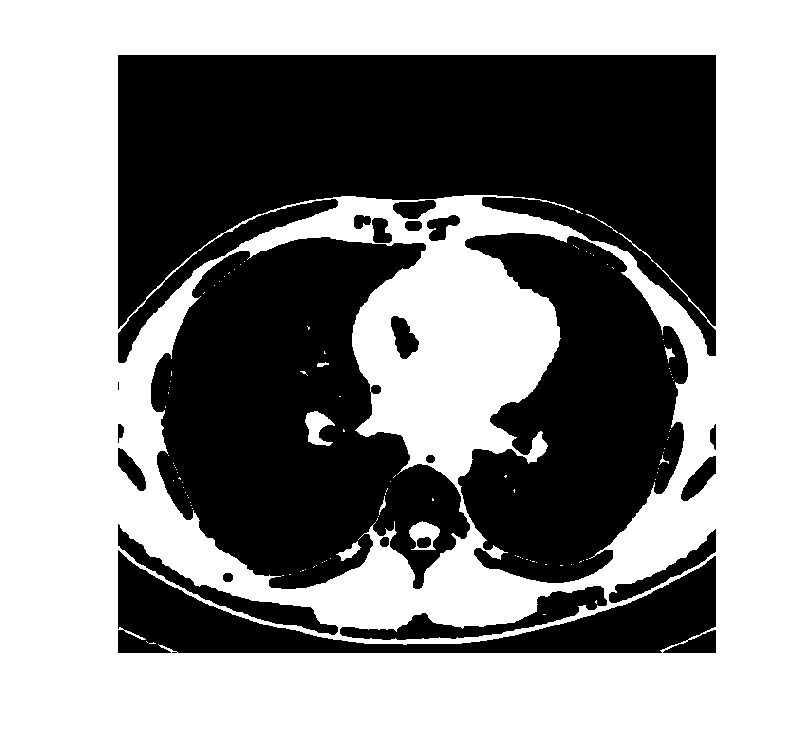


%second label
label_two = L == 2;
% remove false negatives wiht imclose
label_close_two = imclose(label_two,diskse);
imshow(label_close_two)

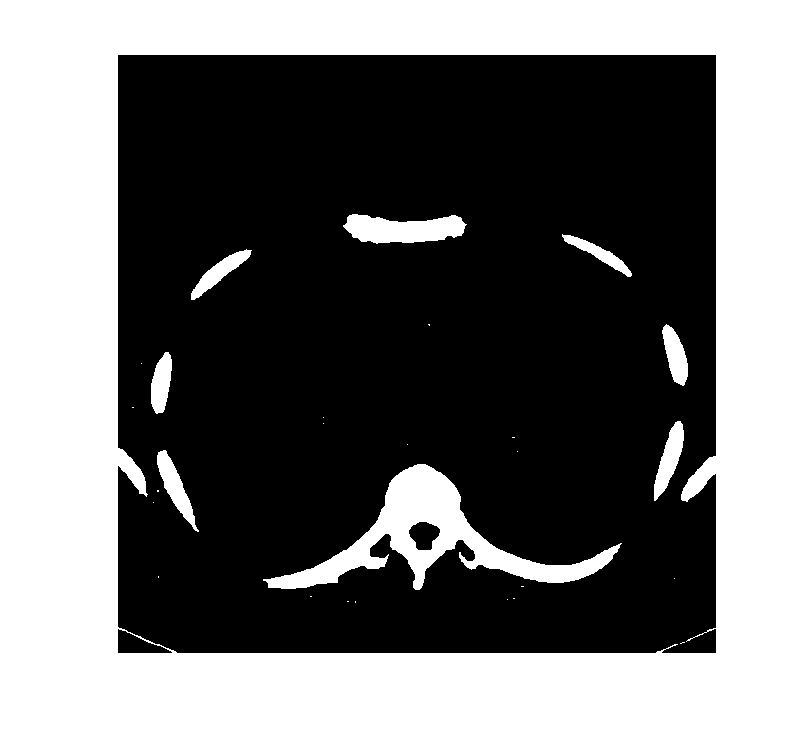


%Third label
label_three = L == 3;
% remove false negatives wiht imclose
label_close_three = imclose(label_three,diskse);
imshow(label_close_three)

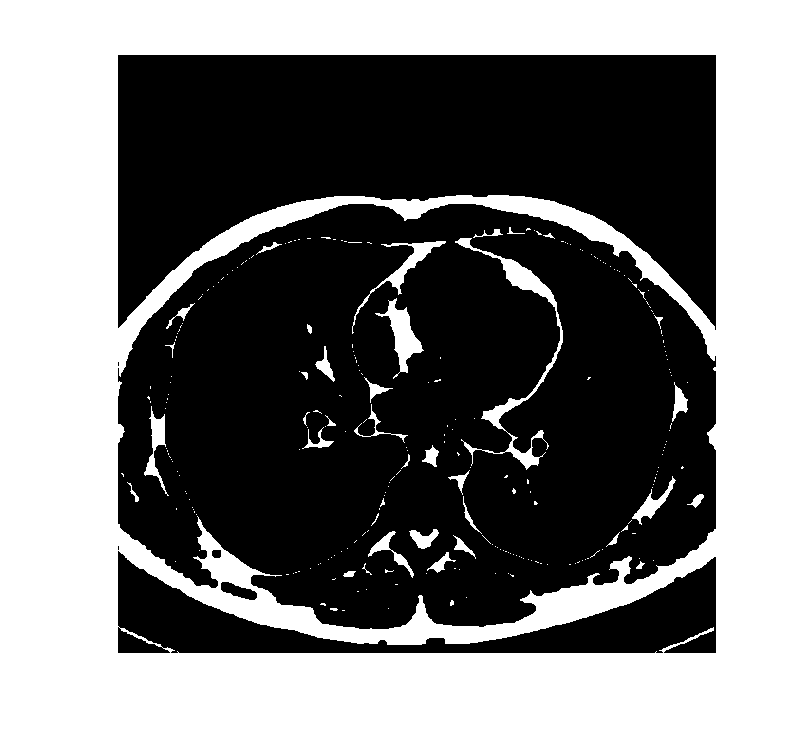


%Fourth label
label_four = L == 4;
% remove false negatives wiht imclose
label_close_four = imclose(label_four,diskse);
imshow(label_close_four)

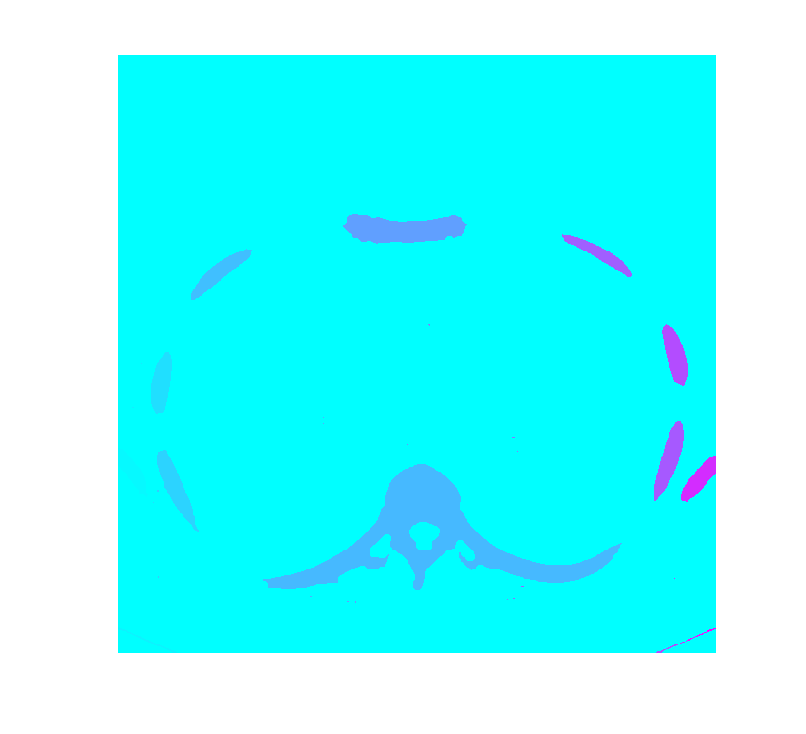



%% Connected components of Label 3

cc = bwconncomp(label_close_three,4);
labeled = labelmatrix(cc);
imshow(labeled,[])
colormap('cool')

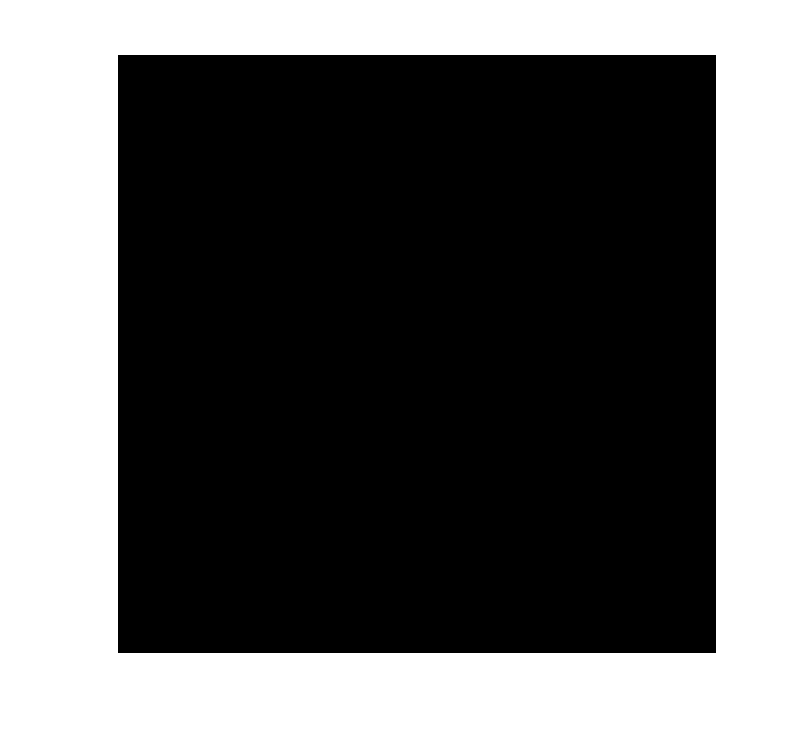


% show left hip
%%
% Using the data tips we find out the label of the left lung
HipLabel = 51;
imshow(labeled==HipLabel,[])

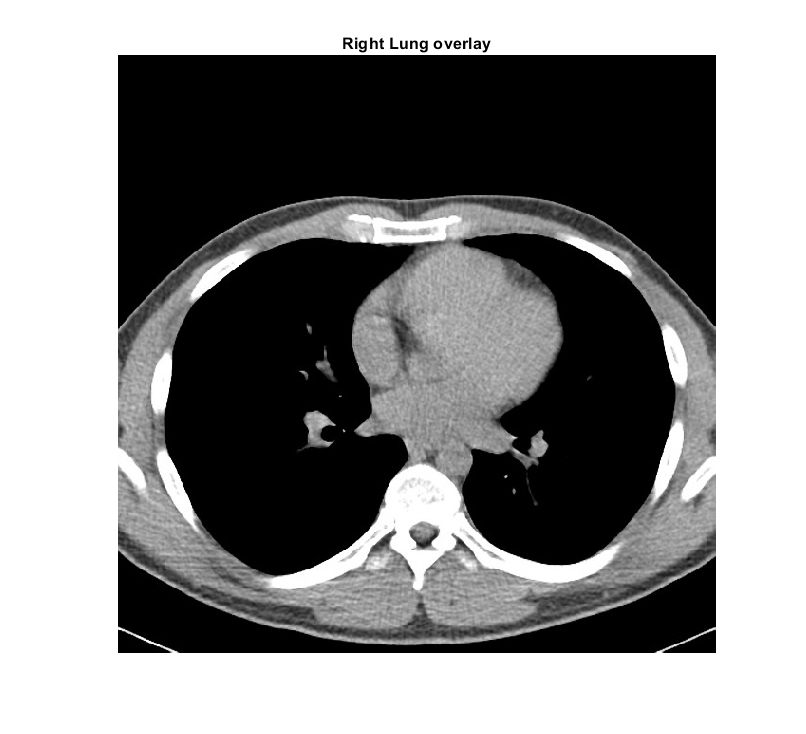

B = labeloverlay(f,labeled==HipLabel);
imshow(B)
title("Right Lung overlay")

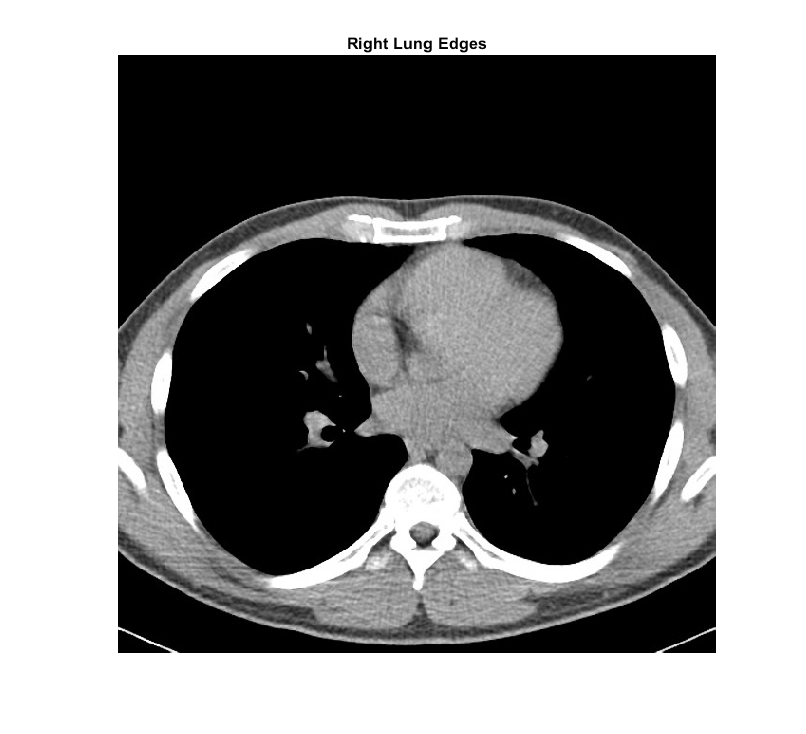

%%
seg1 = labeled==HipLabel;
edgemap = abs(conv2(seg1,dxp,'same'))+abs(conv2(seg1,dyp,'same'));
imshow(f+edgemap,[0,1]);
title("Right Lung Edges")

%%
label_hip = imclose(seg1,diskse11);
imshow(label_hip)

## Watershed segmentation

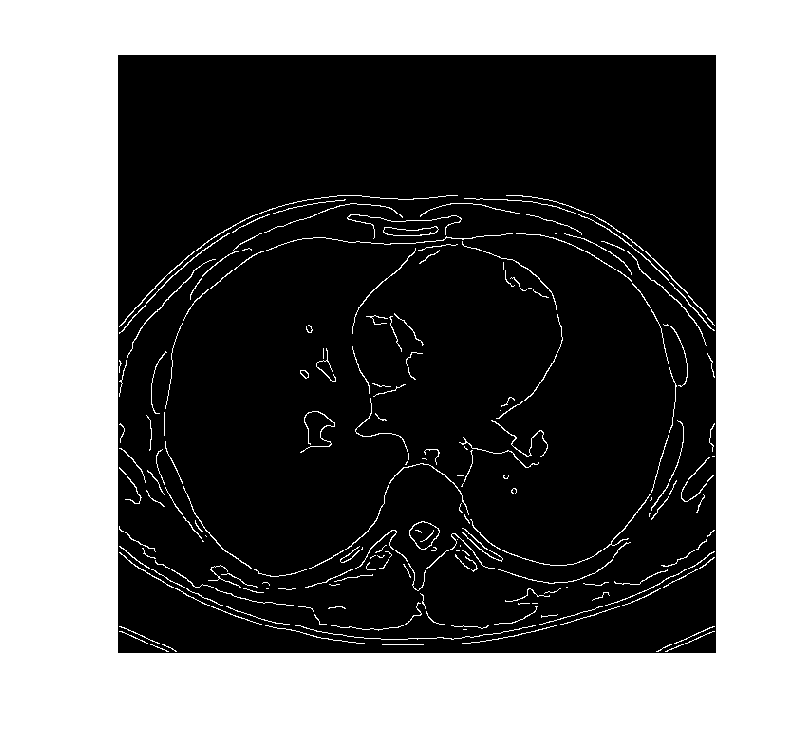

edgeC = edge(f,'Canny',0.2,2);
imshow(edgeC,[])

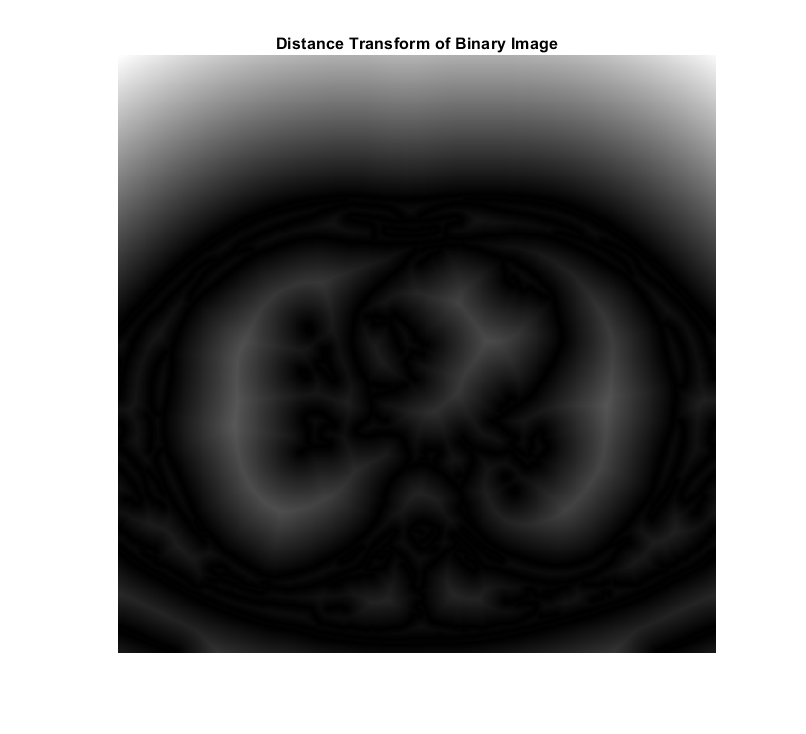

D = bwdist(edgeC);
imshow(D,[])
title('Distance Transform of Binary Image')

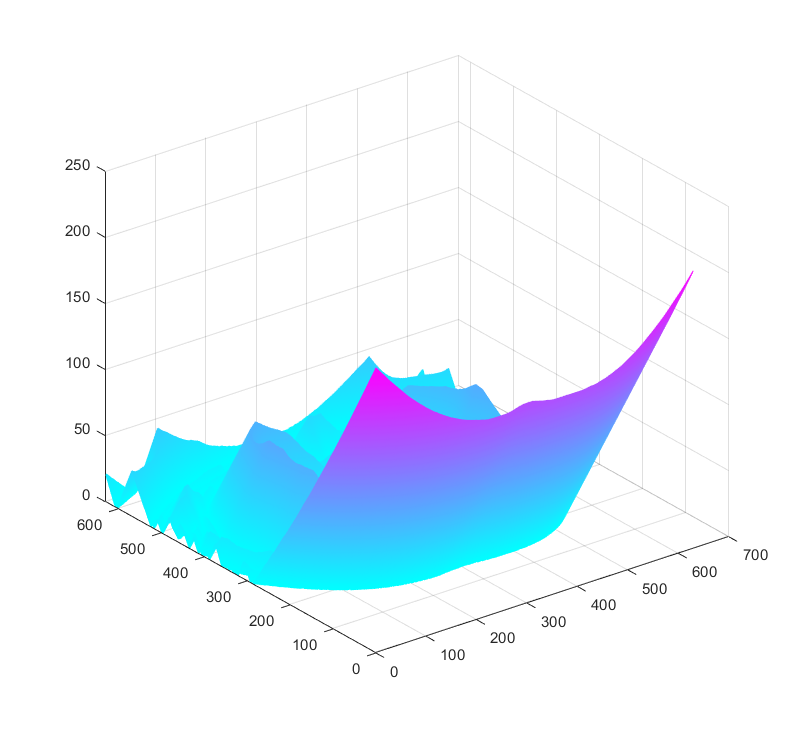

%%
mesh(D)

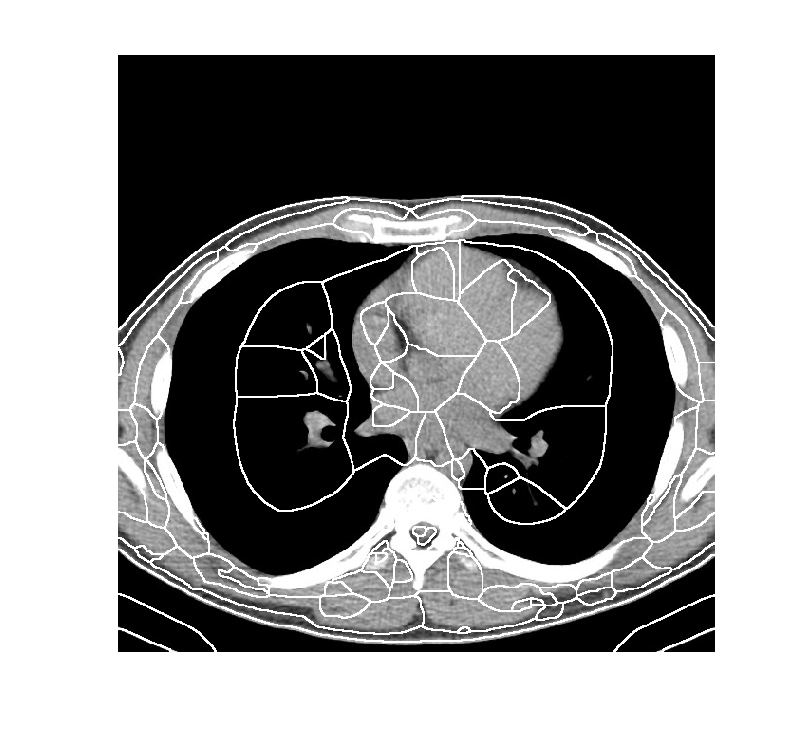

L = watershed(D);
%%
edgemap = abs(conv2(L,dxp,'same'))+abs(conv2(L,dyp,'same'));
imshow(f+edgemap,[0,1]);

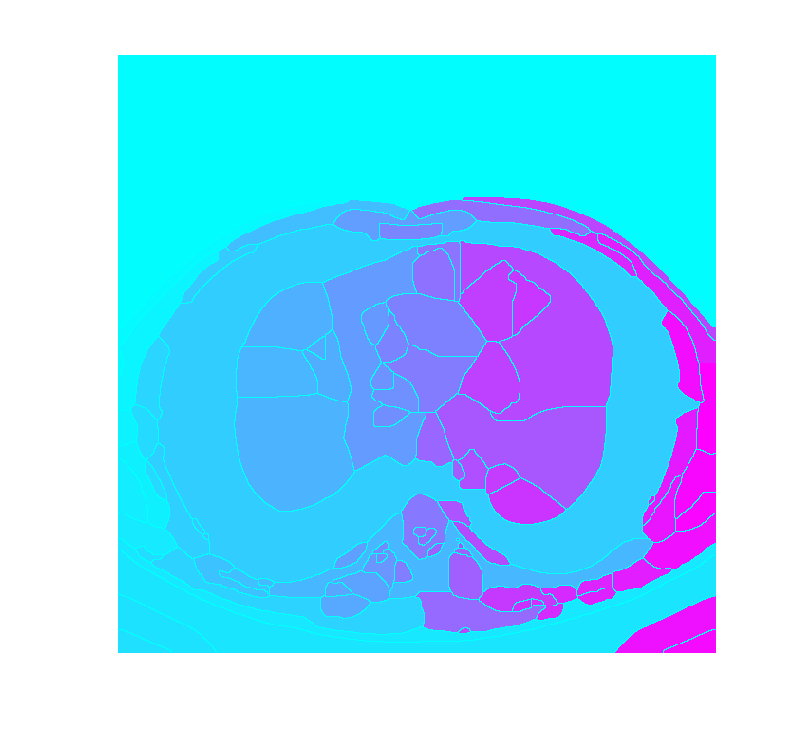

%%
imshow(L,[])
colormap('cool')

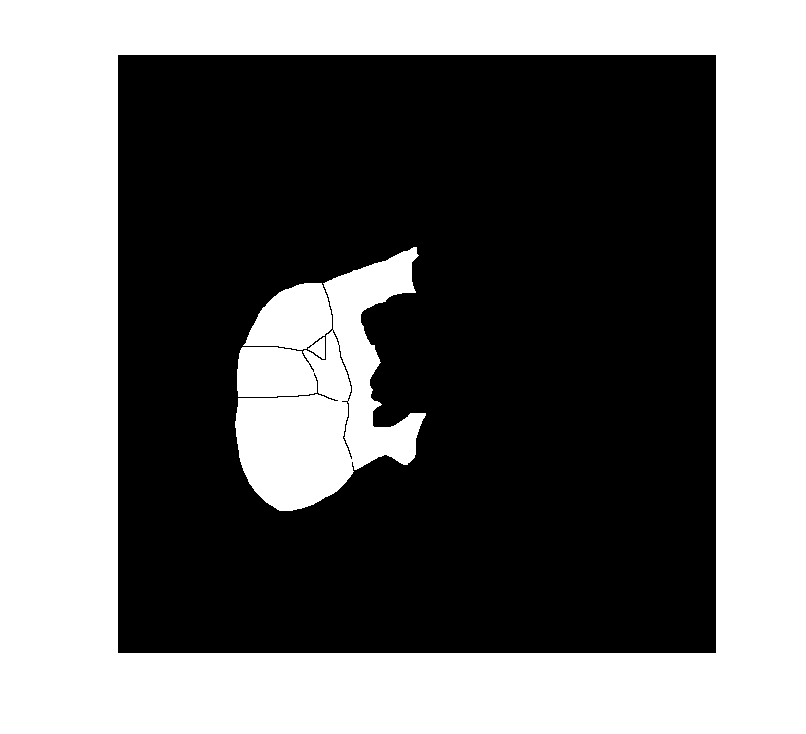

%%
%The lung is made of several components. We must merge the labels
Leftlung = L==29 | L==38 | L==31 | L==28 | L==30 | L==32;

imshow(Leftlung,[])

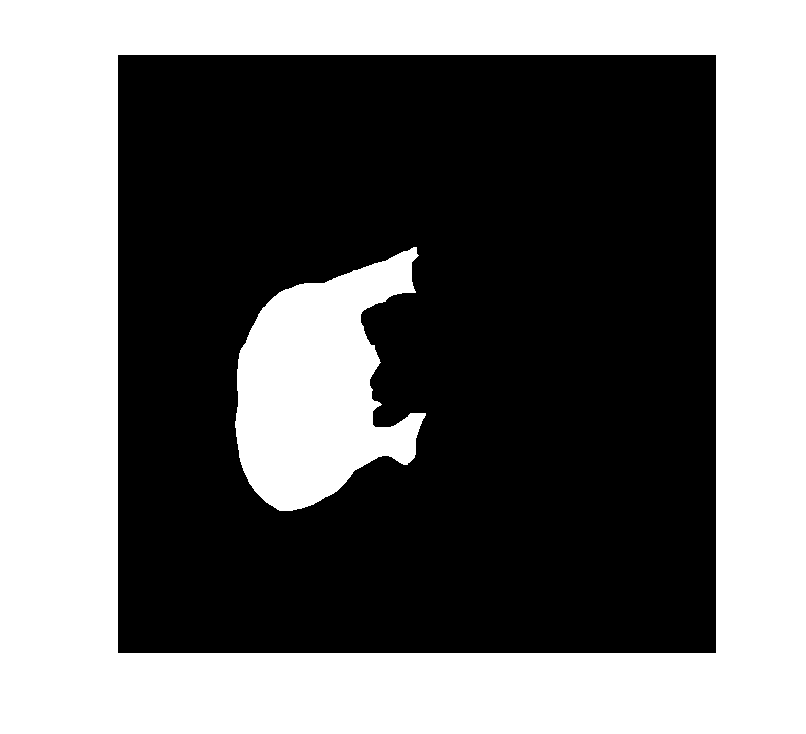

%%
Lefthip_close = imclose(Leftlung,diskse);
imshow(Lefthip_close)

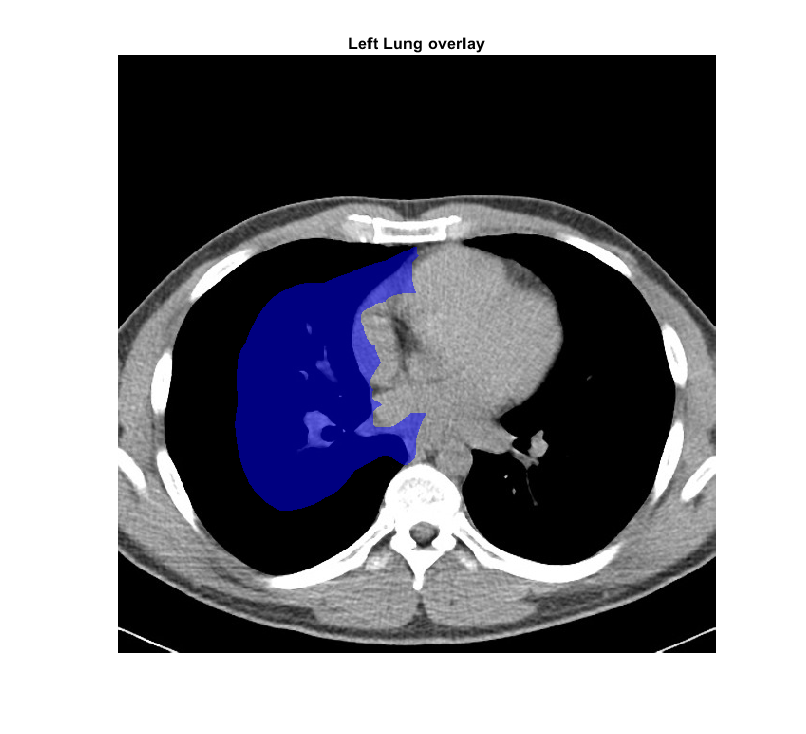

%%
B = labeloverlay(f,Lefthip_close);
imshow(B)
title("Right Lung overlay")

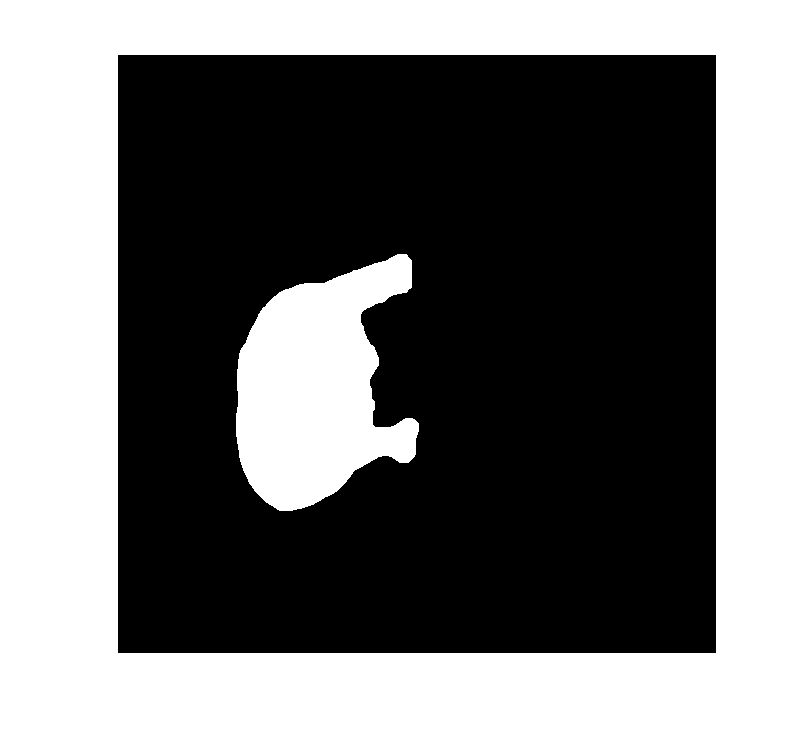


% remove false positives wiht imopen
label_hip = imopen(Lefthip_close,diskse11);
imshow(label_hip)

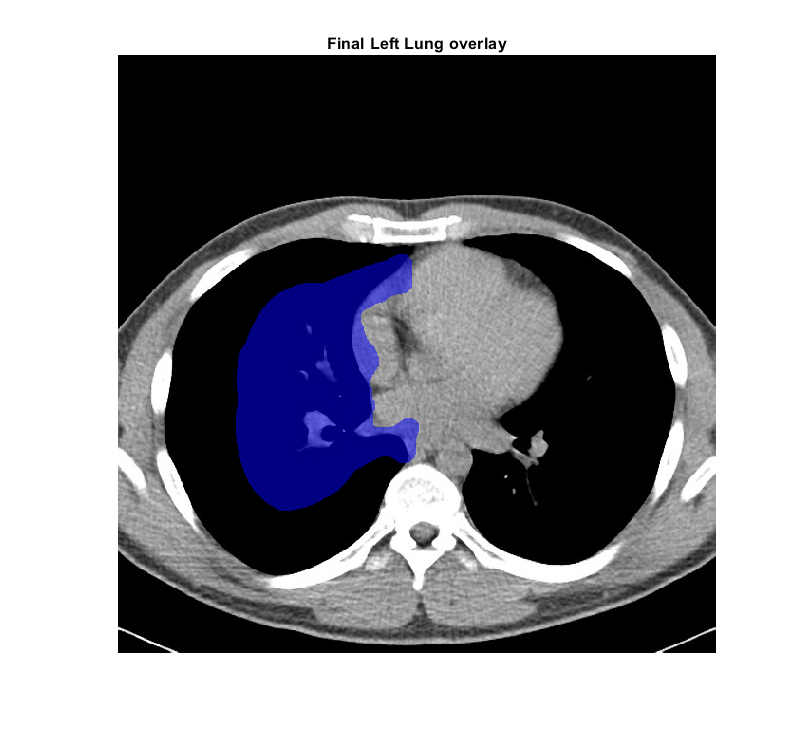


B = labeloverlay(f,label_hip);
imshow(B)
title("Final Right Lung overlay")